En este primer ejercicio se modula una señal de cuatro símbolos en QPSK. Como se puede observar en la figura, se asignan las posiciones (1,1), (-1,-1), (-1,1), (-1,-1) a los pares de bits o símbolos 11, 10, 01, 00 respectivamente.

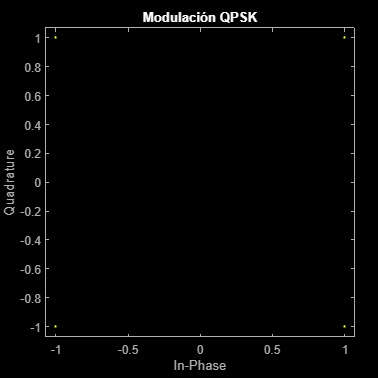

x = [1,1,1,0,0,1,0,0];
xmod = moduladorQPSK(x);

% Modulación QPSK
figure;
scatterplot(xmod);
title('Modulación QPSK')

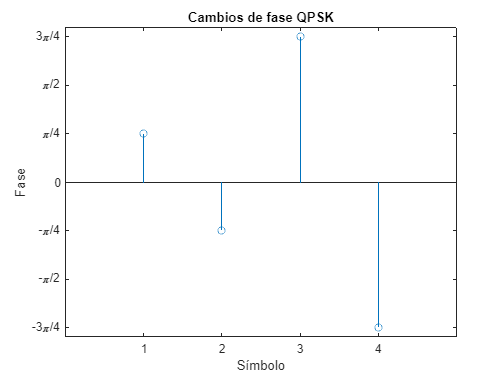

% Gráfico fase QPSK
phasemod = angle(xmod);
figure;
stem(phasemod);
yticks([-pi -3*pi/4 -pi/2 -pi/4 0 pi/4 pi/2 3*pi/4 pi])
yticklabels({'-\pi','-3\pi/4','-\pi/2','-\pi/4','0','\pi/4','\pi/2','3\pi/4','\pi'})
xticks([1 2 3 4])
xlim([0,5])
title('Cambios de fase QPSK')
xlabel('Símbolo')
ylabel('Fase')

Como se puede observar en este gráfico de la fase de la modulación QPSK, existe un salto de 180 grados o paso por cero entre el segundo y tercer símbolo. Esto será analizado en la parte extra al final de esta práctica.

En este ejercicio se vuelve a modular en QPSK. Esta vez a la entrada de la función moduladora se introduce un vector de símbolos aleatorios.

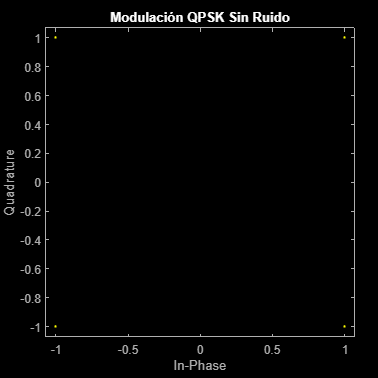

% Generación de vector de bits
Nsymb = 100;                % Número de símbolos en la señal
M = 4;                      % Número de símbolos diferentes disponibles
n = log2(M);                % Número de bits por símbolo
Nbits = n*Nsymb;            % Número de bits total en la señal
x = round(rand(1,Nbits));   % Vector de bits aleatorio
xmod = moduladorQPSK(x);

figure;
scatterplot(xmod);
title('Modulación QPSK Sin Ruido')

Si se introduce ruido en la modulación, se puede observar como las coordenadas, previamente perfectas e invariantes, ahora no son exactamente la unidad (valores discretos entre 1 y -1). Se forma una "nube" de puntos que dificultará la tarea del detector en demodulación.

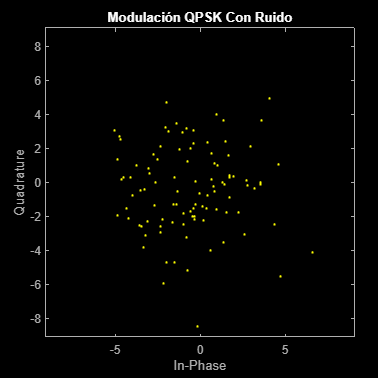

snr = -10;
xmod_noise = awgn(xmod,snr);

figure;
scatterplot(xmod_noise);
title('Modulación QPSK Con Ruido')

En este ejercicio se verifica que el número de errores de la modulación QPSK en ausencia de ruido sea nulo.

% Generación de vector de bits
Nsymb = 10;                 % Número de símbolos en la señal
M = 4;                      % Número de símbolos diferentes disponibles
n = log2(M);                % Número de bits por símbolo
Nbits = n*Nsymb;            % Número de bits total en la señal
x = round(rand(1,Nbits));   % Vector de bits aleatorio

xmod = moduladorQPSK(x);
xdemod = demoduladorQPSK(xmod);
Err = x~=xdemod;
NumErr = sum(Err==1)

NumErr = 0

Al añadirse ruido blanco en la señal modulada, como es de esperar la demodulación presentará errores.

% Generación de vector de bits
Nsymb = 10;                 % Número de símbolos en la señal
M = 4;                      % Número de símbolos diferentes disponibles
n = log2(M);                % Número de bits por símbolo
Nbits = n*Nsymb;            % Número de bits total en la señal
x = round(rand(1,Nbits));   % Vector de bits aleatorio

snr = -10;
xmod = moduladorQPSK(x);
xdemod = demoduladorQPSK(awgn(xmod,snr));
Err = x~=xdemod;
NumErr = sum(Err==1)

NumErr = 6

Una de las variaciones de la modulación QPSK, es por ejemplo DQPSK. En esta modulación la información se envía en el cambio de fase de un símbolo a otro, a diferencia de en QPSK donde se envía la información en un valor de fase concreto, evitando el zero-crossing. A modo de comparación se ofrece las gráficas de probabilidad de error frente a SNR de ambas modulaciones.

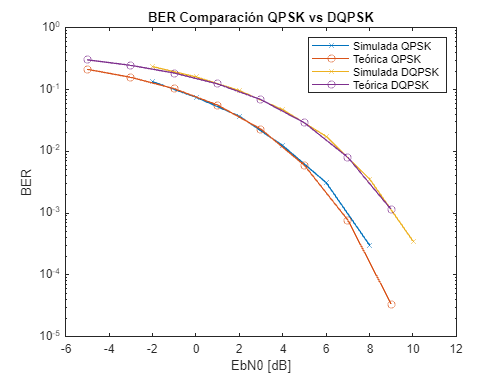

% Generación de vector de bits
Nsymb = 10000;              % Número de símbolos en la señal
M = 4;                      % Número de símbolos diferentes disponibles
n = log2(M);                % Número de bits por símbolo
Nbits = n*Nsymb;            % Número de bits total en la señal
x = round(rand(1,Nbits));   % Vector de bits aleatorio

%Curvas BER QPSK
EbN0_dB = -5:2:10;
EbN0 = 10.^(EbN0_dB/10);
SNR_dB = EbN0_dB + 10*log10(n);

BER_teor_QPSK = qfunc(sqrt(2*EbN0));
BER_teor_QPSK(BER_teor_QPSK<1e-5) = NaN;

BER_teor_DQPSK = 1.13*qfunc(sqrt(1.2*EbN0));
BER_teor_DQPSK(BER_teor_DQPSK<1e-5) = NaN;

PeQPSK = zeros(1,length(SNR_dB));
PeDQPSK = zeros(1,length(SNR_dB));

for i=1:length(SNR_dB)
    xdemodQPSK = demoduladorQPSK(awgn(moduladorQPSK(x),SNR_dB(i)));
    Err = x~=xdemodQPSK;
    NumErr = sum(Err==1);
    PeQPSK(i) = NumErr/Nbits;

    xdemodDQPSK = demoduladorDQPSK(awgn(moduladorDQPSK(x),SNR_dB(i)));
    Err = x~=xdemodDQPSK;
    NumErr = sum(Err==1);
    PeDQPSK(i) = NumErr/Nbits;
end

figure;
grid on;
semilogy(SNR_dB,PeQPSK,'x-');
hold on;
semilogy(EbN0_dB,BER_teor_QPSK,'o-');
semilogy(SNR_dB,PeDQPSK,'x-');
semilogy(EbN0_dB,BER_teor_DQPSK,'o-');
title("BER Comparación QPSK vs DQPSK");
xlabel('EbN0 [dB]');
ylabel('BER');
legend('Simulada QPSK','Teórica QPSK','Simulada DQPSK','Teórica DQPSK');

Como se puede observar en la figura, la probabilidad de error de la modulación DQPSK es mayor a la de QPSK, esto es debido a que un error en un símbolo afectará a los siguientes.

En este ejercicio, además de ruido, se introduce una rotación de fase a la señal modulada, correspondiente con una distorsión de fase que podría haber sido provocado por el canal o la cadena de transmisión.

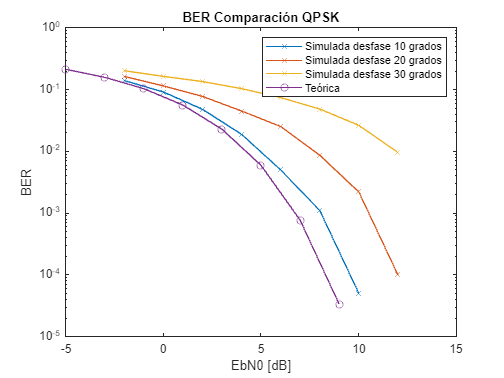

clear all;

% Generación de vector de bits
Nsymb = 10000;              % Número de símbolos en la señal
M = 4;                      % Número de símbolos diferentes disponibles
n = log2(M);                % Número de bits por símbolo
Nbits = n*Nsymb;            % Número de bits total en la señal
x = round(rand(1,Nbits));   % Vector de bits aleatorio

% Rotación fase
phase = [10,20,30];
rot = exp(1j*phase*(pi/180));

%Curvas BER QPSK
EbN0_dB = -5:2:10;
EbN0 = 10.^(EbN0_dB/10);
SNR_dB = EbN0_dB + 10*log10(n);

BER_teor_QPSK = qfunc(sqrt(2*EbN0));
BER_teor_QPSK(BER_teor_QPSK<1e-5) = NaN;

for i=1:length(SNR_dB)
    for j=1:length(rot)
        xmod = moduladorQPSK(x);
        xrot = xmod*rot(j);
        xdemod = demoduladorQPSK(awgn(xrot,SNR_dB(i)));
        Err = x~=xdemod;
        NumErr = sum(Err==1);
        Pe(i,j) = NumErr/Nbits;
    end
end

figure;
grid on;
semilogy(SNR_dB,Pe,'x-');
hold on;
semilogy(EbN0_dB,BER_teor_QPSK,'o-');
title("BER Comparación QPSK");
xlabel('EbN0 [dB]');
ylabel('BER');
legend('Simulada desfase 10 grados','Simulada desfase 20 grados','Simulada desfase 30 grados','Teórica');

Como se puede observar en la figura, a mayor error de fase mayores probabilidades de error a mayor SNR, es decir un peor rendiimiento frente a ruido. Si se introduce este cambio de fase en la modulación DQPSK se observa un fenómeno muy diferente.

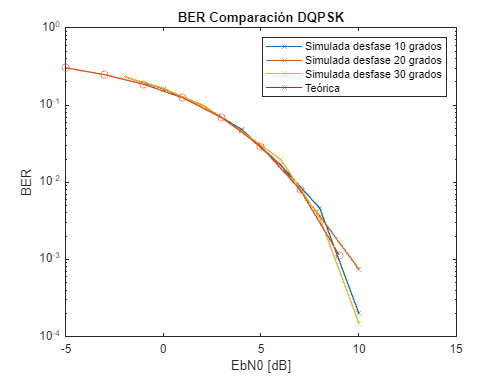

clear all;

% Generación de vector de bits
Nsymb = 10000;              % Número de símbolos en la señal
M = 4;                      % Número de símbolos diferentes disponibles
n = log2(M);                % Número de bits por símbolo
Nbits = n*Nsymb;            % Número de bits total en la señal
x = round(rand(1,Nbits));   % Vector de bits aleatorio

% Rotación fase
phase = [10,20,30];
rot = exp(1j*phase*(pi/180));

%Curvas BER QPSK
EbN0_dB = -5:2:10;
EbN0 = 10.^(EbN0_dB/10);
SNR_dB = EbN0_dB + 10*log10(n);

BER_teor_DQPSK = 1.13*qfunc(sqrt(1.2*EbN0));
BER_teor_DQPSK(BER_teor_DQPSK<1e-5) = NaN;

Pe = zeros(1,length(SNR_dB));

for i=1:length(SNR_dB)
    for j=1:length(rot)
        xmod = moduladorDQPSK(x);
        xrot = xmod*rot(j);
        xdemod = demoduladorDQPSK(awgn(xrot,SNR_dB(i)));
        Err = x~=xdemod;
        NumErr = sum(Err==1);
        Pe(i,j) = NumErr/Nbits;
    end
end

figure;
grid on;
semilogy(SNR_dB,Pe,'x-');
hold on;
semilogy(EbN0_dB,BER_teor_DQPSK,'o-');
title("BER Comparación DQPSK");
xlabel('EbN0 [dB]');
ylabel('BER');
legend('Simulada desfase 10 grados','Simulada desfase 20 grados','Simulada desfase 30 grados','Teórica');

En este caso el error de fase introducido no afecta a la modulación. Esto es debido a que la información en DQPSK viaja en la variación de fase con respecto al símbolo previo, por tanto un error constante en la señal modulada no provocará errores en la demodulación.

Se puede expresar el cambio de fase como $\phi_{i+1} =\phi_i +\Delta \phi_{i+1}$ siendo el término $\Delta \phi_{i+1}$donde viaja la información del siguiente símbolo $i+1$. Si se introduce un error constante $\phi_{\textrm{error}}$, la expresión pasará a ser $\phi_{i+1} +\phi_{\textrm{error}} =\phi_i +\phi_{\textrm{error}} +\Delta \phi_{i+1}$. El error se termina cancelando a sí mismo al ser constante en toda la señal modulada.

En resumen, la modulación DQPSK sufre más probabilidad de error debido a que la demodulación del siguiente símbolo depende del símbolo anterior. Sin embargo, la modulación DQPSK es muy resistente a la distorsión en fase.

En este último ejercicio de la práctica se compara las gráficas de BER de las modulaciones QAM y APSK.

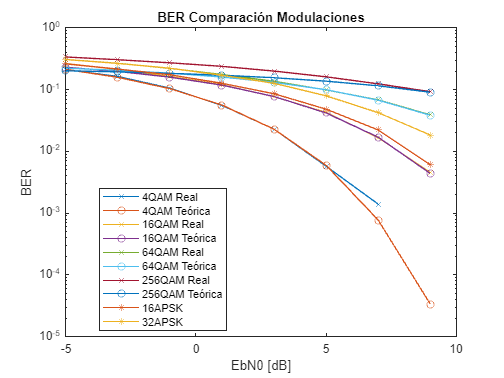

clear all;

Eb_N0_dB = -5:2:10;

[BER_4QAM, BERteor_4QAM] = BER_m_ary_QAM(4, Eb_N0_dB );
[BER_16QAM, BERteor_16QAM] = BER_m_ary_QAM(16, Eb_N0_dB );
[BER_64QAM, BERteor_64QAM] = BER_m_ary_QAM(64, Eb_N0_dB );
[BER_256QAM, BERteor_256QAM] = BER_m_ary_QAM(256, Eb_N0_dB );
BER_16APSK = BER_APSK([4,12], [1,2.5], Eb_N0_dB );
BER_32APSK = BER_APSK([4,12,16], [1,2.5,4.3], Eb_N0_dB );

figure;
grid on;
semilogy(Eb_N0_dB, BER_4QAM, 'x-', 'DisplayName', '4QAM Real');
hold on;
semilogy(Eb_N0_dB, BERteor_4QAM, 'o-', 'DisplayName', '4QAM Teórica');
semilogy(Eb_N0_dB, BER_16QAM, 'x-', 'DisplayName', '16QAM Real');
semilogy(Eb_N0_dB, BERteor_16QAM, 'o-', 'DisplayName', '16QAM Teórica');
semilogy(Eb_N0_dB, BER_64QAM, 'x-', 'DisplayName', '64QAM Real');
semilogy(Eb_N0_dB, BERteor_64QAM, 'o-', 'DisplayName', '64QAM Teórica');
semilogy(Eb_N0_dB, BER_256QAM, 'x-', 'DisplayName', '256QAM Real');
semilogy(Eb_N0_dB, BERteor_256QAM, 'o-', 'DisplayName', '256QAM Teórica');
semilogy(Eb_N0_dB, BER_16APSK, '*-', 'DisplayName', '16APSK');
semilogy(Eb_N0_dB, BER_32APSK, '*-', 'DisplayName', '32APSK');
title("BER Comparación Modulaciones");
xlabel('EbN0 [dB]');
ylabel('BER');
legend('location','best');

La modulación 4-QAM presenta el menor error, con la consecuencia de enviar menor cantidad de información en un mismo periodo de tiempo que otras modulaciones analizadas. Las modulaciones 16-APSK y 16-QAM presentan probabilidades de error frente a SNR muy similares. El peor caso lo presenta la modulación 256-QAM, puesto que aunque contiene el mayor número de símbolos posibles en su constelación, la distancia entre estos es más reducida que en otras versiones de la modulación QAM presentes en el gráfico.

Un buen punto de equilibrio entre las modulaciones presentes son las modulaciones APSK. Estas ofrecen un equilibrio entre modulación en fase y en amplitud, pudiéndose entender como una combinación entrer QPSK y QAM.

La modulación QPSK presenta cambios de fase abruptos que provocan variaciones en la envolvente de la señal modulada, por tanto la información ahora viaja en la amplitud puesto que esta ha sido modificada. Esto provoca que en QPSK se deben emplear amplificadores lineales para evitar destruir la información. Con menor eficiencia energética que amplificadores menos lineales. Además, esta variación en la envolvente introduce un valor medio a la señal que dificulta el filtrado de la señal modulada en banda base.

Una posible solución a este fenómeno (además de la modulación DQPSK vista anteriormente) es la modulación OQPSK. Al contrario que QPSK, la modulación OQPSK permite que se pueda filtrar en banda base la señal digital moduladora, y por tanto reducir el ancho de banda de la señal modulada, sin introducir una modulación de amplitud significativa. Esto es así  porque al filtrar la modulación de amplitud se produce distorsión principalmente en los cruces por cero de la señal modulada, y la señal OQPSK no tiene cruces por cero. Lo anterior se traduce en que en OQPSK se pueden emplear amplificadores no tan lineales como en QPSK, con mayor eficiencia energética.

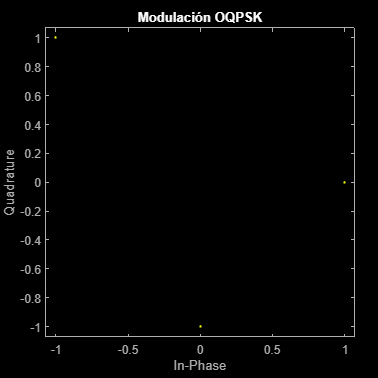

clear all;

x = [1,1,0,0];
xmodO = moduladorOQPSK(x);
xmod = moduladorQPSK(x);

figure;
scatterplot(xmodO);
title('Modulación OQPSK');

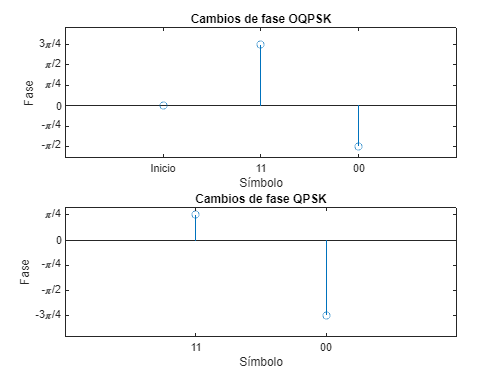

% Gráfico fase OQPSK vs QPSK
phasemodO = angle(xmodO);
phasemod = angle(xmod);
figure;
subplot(2,1,1);
stem(phasemodO);
yticks([-pi -3*pi/4 -pi/2 -pi/4 0 pi/4 pi/2 3*pi/4 pi])
yticklabels({'-\pi','-3\pi/4','-\pi/2','-\pi/4','0','\pi/4','\pi/2','3\pi/4','\pi'})
xticks([1 2 3])
xlim([0,4])
xticklabels({'Inicio','11','00'})
title('Cambios de fase OQPSK')
xlabel('Símbolo')
ylabel('Fase')

subplot(2,1,2);
stem(phasemod);
yticks([-pi -3*pi/4 -pi/2 -pi/4 0 pi/4 pi/2 3*pi/4 pi])
yticklabels({'-\pi','-3\pi/4','-\pi/2','-\pi/4','0','\pi/4','\pi/2','3\pi/4','\pi'})
xticks([1 2])
xlim([0,3])
xticklabels({'11','00'})
title('Cambios de fase QPSK')
xlabel('Símbolo')
ylabel('Fase')

Como se puede observar en la primera figura de este subplot, en la modulación OQPSK ya no se produce un cambio de fase de $\pi$ entre símbolos opuestos (11 y 00, cambian todos los bits). En OQPSK se pasa a tener un cambio de fase de $3\pi/4$, evitándose el cruce por cero y la consecuente modulación en amplitud de la envolvente. El primer símbolo de la modulación OQPSK no debe tenerse en cuenta, puesto que se trata de un estado de inicialización.

Sin embargo, las modulaciónes QPSK y OQPSK presentará la misma probabilidad de error. Esto se puede observar en el siguiente gráfico.

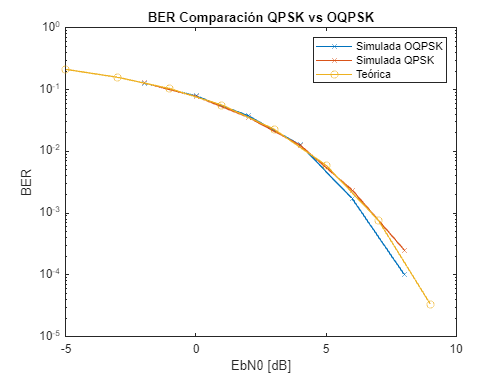

% Generación de vector de bits
Nsymb = 10000;              % Número de símbolos en la señal
M = 4;                      % Número de símbolos diferentes disponibles
n = log2(M);                % Número de bits por símbolo
Nbits = n*Nsymb;            % Número de bits total en la señal
x = round(rand(1,Nbits));   % Vector de bits aleatorio

%Curvas BER QPSK
EbN0_dB = -5:2:10;
EbN0 = 10.^(EbN0_dB/10);
SNR_dB = EbN0_dB + 10*log10(n);

BER_teor = qfunc(sqrt(2*EbN0));
BER_teor(BER_teor<1e-5) = NaN;

PeOQPSK = zeros(1,length(SNR_dB));
PeQPSK = zeros(1,length(SNR_dB));

for i=1:length(SNR_dB)
    xmod = moduladorOQPSK(x);
    xdemod = demoduladorOQPSK(awgn(xmod,SNR_dB(i)));
    Err = x~=xdemod;
    NumErr = sum(Err==1);
    PeOQPSK(i) = NumErr/Nbits;

    xmod = moduladorQPSK(x);
    xdemod = demoduladorQPSK(awgn(xmod,SNR_dB(i)));
    Err = x~=xdemod;
    NumErr = sum(Err==1);
    PeQPSK(i) = NumErr/Nbits;
end

figure;
grid on;
semilogy(SNR_dB,PeOQPSK,'x-');
hold on;
semilogy(SNR_dB,PeQPSK,'x-');
semilogy(EbN0_dB,BER_teor,'o-');
title("BER Comparación QPSK vs OQPSK");
xlabel('EbN0 [dB]');
ylabel('BER');
legend('Simulada OQPSK','Simulada QPSK','Teórica');

Como se puede observar, las probabilidades de error son prácticamente idénticas. Esto es debido a que la operación de retardo realizada en la rama Q del modulador OQPSK es una operación lineal, por tanto el BER no se verá afectado. 

En conclusión, la probabilidad de error no se verá afectada. Sin embargo con OQPSK no se producirán cambios abruptos de fase con la consecuente modificación de la envolvente de la señal modulada. Esto permite utilizar amplificadores menos lineales más eficientes en energía y un filtrado en banda base más sencillo y limpio.

function rxBits = demoduladorOQPSK(rxSimbol)
% Se reduce en uno la longitud del vector de bits resultante debido
% al estado de inicialización de la modulación OQPSK.
n = length(rxSimbol)-1;
rxBits = zeros(1, 2*n);

% Se elimina la parte imaginaria del primer simbolo y la parte real
% del ultimo. Esto es equivalente a deshacer la inserción deliberada 
% de ceros al principio del vector Q y al final del vector I realizada 
% en la modulación.
rxSimbol(1) = real(rxSimbol(1));
rxSimbol(end) = imag(rxSimbol(end))*1j;

% Copia de rxSimbol a vector fila
b = rxSimbol(:).';

% Se generan los vectores I (fase) y Q (cuadratura)
I   = zeros(1,n);
ind = find(real(b)>0);
I(ind) = 1;
Q   = zeros(1,n);
ind = find(imag(b)>0);

% Se resta uno a la posición en cuadratura obtenida para deshacer 
% el retardo introducido previamente en modulación.
ind_delayed = ind-1;

% Para asegurarse que no se provoca error por indices nulos al realizar
% la operacion de reshape, es necesario eliminar aquellos valores nulos 
% de los indices calculados
ind_sanitized = nonzeros(ind_delayed)';
Q(ind_sanitized) = 1;

% Se genera el vector de bits en base a I y Q
rxBits = reshape([I ; Q], 1, 2*n);
end

function xMod = moduladorOQPSK(txBits)
% Comprobación de que la longitud de txBits es par
n = length(txBits);
if rem(n,2) ~ 0;
    error('La longitud de txBits no es par');
end

% Copia de txBits a vector fila
b = txBits(:)';

% Se generan los vectores I (fase) y Q (cuadratura)
% Los 1s se asimilan a fase 0 (+1) y los 0s a fase pi (-1)
b = (reshape(b', 2, n/2) - 0.5)*2;
I = b(1,:);
Q = b(2,:);

% Añadir retardo de medio símbolo (equivalente a una muestra) a una de las ramas
Q = [0,Q];

% Igualar la longitud de los vectores
I = [I,0];

% Se genera la señal modulada como suma de señales BPSK en fase y cuadratura
xMod = I + 1j*Q;
end